load('MaxMelDER_CCTSweep_DUV0.mat')
[a,b] = max( (reshape( [SweepStructArray2d.melOpicDER], height(SweepStructArray2d),[])), [],1,'linear'); %max of each column

Smax = SweepStructArray2d(b);

load('MinMelDER_CCTSweep_LMSRef_111521.mat')
Smin = SweepStructArray2d;


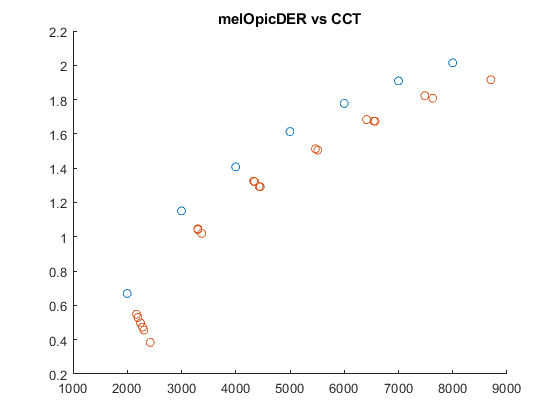

tiledlayout('flow')

scatter([Smax.cct], [Smax.melOpicDER])
hold on
scatter([Smin.cct], [Smin.melOpicDER])
title('melDER vs CCT')
title('melOpicDER vs CCT')

nexttile

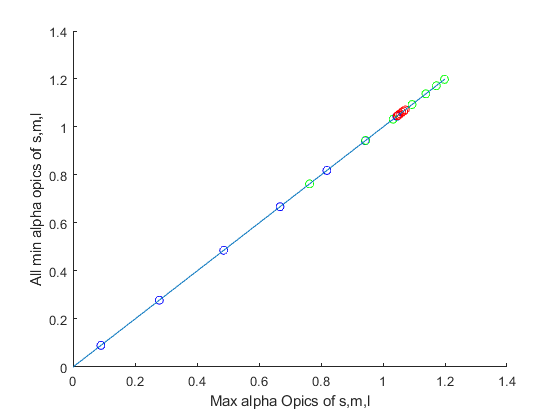

scatter([Smax.sOpicDER], reshape([Smin.sOpicDER],length(Smin),[]),'b')
hold on
scatter([Smax.mOpicDER],  reshape([Smin.mOpicDER],length(Smin),[]),'g')

scatter([Smax.lOpicDER],  reshape([Smin.lOpicDER],length(Smin),[]),'r')
line([0,max(get(gca,'XTick'))],[0,max(get(gca,'YTick'))] );
xlabel('Max alpha Opics of s,m,l')
ylabel('All min alpha opics of s,m,l')



figure

 reshape([Smin.sOpicDER],height(Smin),[]) - Smax.sOpicDER
  reshape([Smin.mOpicDER],height(Smin),[]) - Smax.mOpicDER

   reshape([Smin.lOpicDER],height(Smin),[]) - Smax.lOpicDER

   %%
   %%


diffMAT =  reshape([Smin.melOpicDER],height(Smin),[]) - [Smax.melOpicDER]

diffMAT =      -0.12106     -0.10904     -0.11644     -0.10855     -0.10381     -0.10075     -0.09866
     -0.28525       -0.131    -0.082883     -0.10855     -0.10245     -0.10075     -0.09866
     -0.28525     -0.10433     -0.11644     -0.10855     -0.10381     -0.10075     -0.09866
     -0.17185       -0.131     -0.11644     -0.10855     -0.09385    -0.085811     -0.09866
     -0.21361       -0.131     -0.11644     -0.10855     -0.10381     -0.10075     -0.09866
     -0.28525       -0.131     -0.11644     -0.10855     -0.10381     -0.10075     -0.09866
     -0.13991       -0.131     -0.11399     -0.10855     -0.10381     -0.10075     -0.09866
     -0.28525       -0.131     -0.11644     -0.10855     -0.10381     -0.10075     -0.09866
     -0.17122       -0.131     -0.08604     -0.10048     -0.10381     -0.10075     -0.09866
     -0.19629       -0.131     -0.11644     -0.10855     -0.10381     -0.10075     -0.09866



[a,b] = max( abs(diffMAT),[],1,'linear'); %max of each column


SminBest = Smin(b)

SminBest = 1×7 struct array with fields:
    s
    wl
    sref
    stest
    stest0
    t2XYZ
    t2xy
    t10XYZ
    t10xy
    r2XYZ
    r10XYZ
    cct
    duv
    rf
    rg
    hsBins
    csBins
    rfBins
    gref
    gtest
    sOpicDER
    mOpicDER
    lOpicDER
    melOpicDER
    rOpicDER
    ELR2
    spdPercents
    spdChannels
    perc_0
    myUiCon
    myUiFun


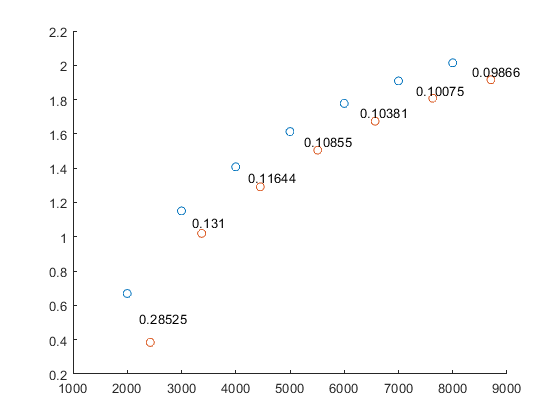

   %%
   
   
figure
scatter([Smax.cct],[Smax.melOpicDER])
hold on
scatter([Smin(b).cct],[Smin(b).melOpicDER])

text( mean( [Smax.cct;Smin(b).cct] ),...
    mean([Smax.melOpicDER;Smin(b).melOpicDER]),...
    string([Smax.melOpicDER]-[Smin(b).melOpicDER] ) )


% nexttile
% scatter([Smax.cct], [Smax.sOpicDER])
% hold on
% scatter([Smin.cct], [Smin.sOpicDER])
% title('sOpicDER vs cct')
% 
% nexttile
% scatter([Smax.cct], [Smax.mOpicDER])
% hold on
% scatter([Smin.cct], [Smin.mOpicDER])
% title('mOpicDER vs cct')
% 
% nexttile
% scatter([Smax.cct], [Smax.lOpicDER])
% hold on
% scatter([Smin.cct], [Smin.lOpicDER])
% title('mOpicDER vs cct')

% nexttile
% scatter([Smax.cct], norm([Smax.lOpicDER]',[Smin.lOpicDER'])
% hold on
% scatter([Smin.cct], [Smin.lOpicDER])
% 
% nexttile
% scatter([Smax.cct], norm( [Smax])
% hold on
% scatter([Smin.cct], [Smin.mOpicDER])